# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

Forecasts of 2022 are based on the in-sample estimation of 2021.

1.The difference between "exercise_VolForecastRV20220701.mlx" is that we adjust RSGARCH and HAR

clc,clear
addpath("data_Files/")
addpath("results_Files/");

## SP500

estimation window = 750

Time: 

Results: 

datatable=readtable("SP500_0608.xlsx");
name='SP500';
window_size = 750;
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
% volatility forecast
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_GJR=zeros(n,1);
vf_CPGJR=zeros(n,1);
vf_CPGJRiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
% in-sample fitness
ismae_GARCH=zeros(n,1);
isrmse_GARCH=zeros(n,1);
ismae_CPGARCH=zeros(n,1);
isrmse_CPGARCH=zeros(n,1);
ismae_CPGARCHiteration=zeros(n,1);
isrmse_CPGARCHiteration=zeros(n,1);
ismae_GJR=zeros(n,1);
isrmse_GJR=zeros(n,1);
ismae_CPGJR=zeros(n,1);
isrmse_CPGJR=zeros(n,1);
ismae_CPGJRiteration=zeros(n,1);
isrmse_CPGJRiteration=zeros(n,1);
ismae_RSGARCH=zeros(n,1);
isrmse_RSGARCH=zeros(n,1);
ismae_CPRSGARCH=zeros(n,1);
isrmse_CPRSGARCH=zeros(n,1);
ismae_CPRSGARCHiteration=zeros(n,1);
isrmse_CPRSGARCHiteration=zeros(n,1);
ismae_HAR=zeros(n,1);
isrmse_HAR=zeros(n,1);
ismae_CPHAR=zeros(n,1);
isrmse_CPHAR=zeros(n,1);
ismae_CPHARiteration=zeros(n,1);
isrmse_CPHARiteration=zeros(n,1);
% cluster number
K_GARCH=zeros(n,1);
K_GJR=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);
% dynamic parameter 
para_GARCH=zeros(n,3);
para_GJR=zeros(n,4);
para_RSGARCH=zeros(2,3,n);
transM_RSGARCH=zeros(2,2,n);
para_HAR=zeros(n,7);

% initial setting
i1=0;I=find(oos_index==1);

% itinial value of RSGARCH
addpath("m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[0.1 0.1 0.82;0.01 0.01 0.5];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.param_dist=[];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation,~] = swgarch(datatable.Return(I(1)-window_size:I(1)-1),Mdl_RSGARCH.k, ...
    Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
    Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
rmpath("m_Files_swgarch")

for i=I(1):I(end)
    i1=i1+1
    index=i-window_size:i-1;
    ret=datatable.Return(index);

HAR

    Jump=zeros(size(datatable.RV(index)));
    index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
    Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    para_HAR(i1,:)=paras;
    ismae_HAR(i1)=mean(abs(v_HAR-ret.^2));
    isrmse_HAR(i1)=sqrt(mean((v_HAR-ret.^2).^2));
    %% CP-HAR
    [LB,J,~]=Fisher_div_sqr(v_HAR,20);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [v_CPHAR,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHAR(i1)=mean(abs(v_CPHAR-ret.^2));
    isrmse_CPHAR(i1)=sqrt(mean((v_CPHAR-ret.^2).^2));
    %% CP-HAR-Ite.
    [v_CPHARiteration,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR, ...
        [vt_1,vt_5,vt_22,Jump,a1,a2],20);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHARiteration(i1)=mean(abs(v_CPHARiteration-ret.^2));
    isrmse_CPHARiteration(i1)=sqrt(mean((v_CPHARiteration-ret.^2).^2));

GARCH

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};
    para_GARCH(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
    ismae_GARCH(i1)=mean(abs(v_GARCH-ret.^2));
    isrmse_GARCH(i1)=sqrt(mean((v_GARCH-ret.^2).^2));
    %% CP-GARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,10);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCH(i1)=mean(abs(v_CPGARCH-ret.^2));
    isrmse_CPGARCH(i1)=sqrt(mean((v_CPGARCH-ret.^2).^2));
    %% CP-GARCH-Ite.
    [v_CPGARCHiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GARCH,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCHiteration(i1)=mean(abs(v_CPGARCHiteration-ret.^2));
    isrmse_CPGARCHiteration(i1)=sqrt(mean((v_CPGARCHiteration-ret.^2).^2));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJR = infer(EstMdl,ret);
    vf_GJR(i1)=forecast(EstMdl,1,ret);
    para_GJR(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1},EstMdl.Leverage{1}];
    ismae_GJR(i1)=mean(abs(v_GJR-ret.^2));
    isrmse_GJR(i1)=sqrt(mean((v_GJR-ret.^2).^2));
    %% CP-GJR
    [LB,J,~]=Fisher_div_sqr(v_GJR,10);
    K = OptimalClusterNumber(v_GJR,LB);
    K_GJR(i1)=K;
    [v_CPGJR,Nodes]=Vol_ClusterPartition(v_GJR,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJR(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJR(i1)=mean(abs(v_CPGJR-ret.^2));
    isrmse_CPGJR(i1)=sqrt(mean((v_CPGJR-ret.^2).^2));
    %% CP-GJR-Ite.
    [v_CPGJRiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GJR,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJRiteration(i1)=mean(abs(v_CPGJRiteration-ret.^2));
    isrmse_CPGJRiteration(i1)=sqrt(mean((v_CPGJRiteration-ret.^2).^2));

RSGARCH

    addpath("m_Files_swgarch")

    Mdl_RSGARCH.startvalG=estimation.garch;
    Mdl_RSGARCH.startvalM=estimation.transM;
    [estimation,probabilities] = swgarch(ret,Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation.garch,...
        estimation.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret,estimation.H,probabilities);
    para_RSGARCH(:,:,i1)=estimation.garch;
    transM_RSGARCH(:,:,i1)=estimation.transM;
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;
    ismae_RSGARCH(i1)=mean(abs(v_RSGARCH-ret.^2));
    isrmse_RSGARCH(i1)=sqrt(mean((v_RSGARCH-ret.^2).^2));
    %% CP-RSGARCH
    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,50);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;
    ismae_CPRSGARCH(i1)=mean(abs(v_CPRSGARCH-ret.^2));
    isrmse_CPRSGARCH(i1)=sqrt(mean((v_CPRSGARCH-ret.^2).^2));
    %% CP-RSGARCH-Ite.
    [v_CPRSGARCHiteration,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH,Mdl_RSGARCH,50);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;
    ismae_CPRSGARCHiteration(i1)=mean(abs(v_CPRSGARCHiteration-ret.^2));
    isrmse_CPRSGARCHiteration(i1)=sqrt(mean((v_CPRSGARCHiteration-ret.^2).^2));

    rmpath("m_Files_swgarch")
end

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJR, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJR, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");
set(gcf,'Position',[500 500 900 300]);

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of parameters in each estimation window

GARCH

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GARCH(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GARCH(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GARCH(:,3),"Color",col(3,:));
subtitle("GARCH")

GJR

col=rainbow(4);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GJR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GJR(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GJR(:,3),"Color",col(3,:));
subtitle("GARCH")
subplot(2,2,4);
plot(Timeline_outsample,para_GJR(:,4),"Color",col(4,:));
subtitle("Leverage")

RSGARCH

figure;
col=rainbow(2);
subplot(2,2,1);
plot(Timeline_outsample,reshape(para_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,1,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("\omega")
subplot(2,2,2);
plot(Timeline_outsample,reshape(para_RSGARCH(1,2,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("arch parameter")
subplot(2,2,3);
plot(Timeline_outsample,reshape(para_RSGARCH(1,3,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,3,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("garch parameter")
subplot(2,2,4);
plot(Timeline_outsample,reshape(transM_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(transM_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("transfer matrix")

HAR

col=rainbow(7);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,2),"Color",col(2,:));
subtitle("v_{t-1}")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,3),"Color",col(3,:));
subtitle("v_{t-5}")
subplot(2,2,4);
plot(Timeline_outsample,para_HAR(:,4),"Color",col(4,:));
subtitle("v_{t-22}")
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,5),"Color",col(5,:));
subtitle("b_J")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,6),"Color",col(6,:));
subtitle("a_1")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,7),"Color",col(7,:));
subtitle("a_2")

#### Figure of optimal cluster number in each estimation window

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJR,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### Figure of in-sample MAE and MSE

figure;
col=rainbow(12);
plot(Timeline_outsample,ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,ismae_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,ismae_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,ismae_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,ismae_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")
figure;
plot(Timeline_outsample,isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,isrmse_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,isrmse_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,isrmse_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,isrmse_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

DM test

table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJR]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJR]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### Figure of volatility persistence

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size750_20220704'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJR","vf_CPGJR","vf_CPGJRiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJR","K_RSGARCH","K_HAR", ...
    "para_HAR","para_GARCH","para_GJR","para_RSGARCH","transM_RSGARCH", ...
    "ismae_GARCH","isrmse_GARCH","ismae_CPGARCH","isrmse_CPGARCH","ismae_CPGARCHiteration","isrmse_CPGARCHiteration", ...
    "ismae_GJR","isrmse_GJR","ismae_CPGJR","isrmse_CPGJR","ismae_CPGJRiteration","isrmse_CPGJRiteration", ...
    "ismae_RSGARCH","isrmse_RSGARCH","ismae_CPRSGARCH","isrmse_CPRSGARCH","ismae_CPRSGARCHiteration","isrmse_CPRSGARCHiteration", ...
    "ismae_HAR","isrmse_HAR","ismae_CPHAR","isrmse_CPHAR","ismae_CPHARiteration","isrmse_CPHARiteration");

## DAX

estimation window = 750

Time: 

Results: 

datatable=readtable("DAX_0608.xlsx");
name='DAX';
window_size = 750;
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
% volatility forecast
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_GJR=zeros(n,1);
vf_CPGJR=zeros(n,1);
vf_CPGJRiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
% in-sample fitness
ismae_GARCH=zeros(n,1);
isrmse_GARCH=zeros(n,1);
ismae_CPGARCH=zeros(n,1);
isrmse_CPGARCH=zeros(n,1);
ismae_CPGARCHiteration=zeros(n,1);
isrmse_CPGARCHiteration=zeros(n,1);
ismae_GJR=zeros(n,1);
isrmse_GJR=zeros(n,1);
ismae_CPGJR=zeros(n,1);
isrmse_CPGJR=zeros(n,1);
ismae_CPGJRiteration=zeros(n,1);
isrmse_CPGJRiteration=zeros(n,1);
ismae_RSGARCH=zeros(n,1);
isrmse_RSGARCH=zeros(n,1);
ismae_CPRSGARCH=zeros(n,1);
isrmse_CPRSGARCH=zeros(n,1);
ismae_CPRSGARCHiteration=zeros(n,1);
isrmse_CPRSGARCHiteration=zeros(n,1);
ismae_HAR=zeros(n,1);
isrmse_HAR=zeros(n,1);
ismae_CPHAR=zeros(n,1);
isrmse_CPHAR=zeros(n,1);
ismae_CPHARiteration=zeros(n,1);
isrmse_CPHARiteration=zeros(n,1);
% cluster number
K_GARCH=zeros(n,1);
K_GJR=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);
% dynamic parameter 
para_GARCH=zeros(n,3);
para_GJR=zeros(n,4);
para_RSGARCH=zeros(2,3,n);
transM_RSGARCH=zeros(2,2,n);
para_HAR=zeros(n,7);

% initial setting
i1=0;I=find(oos_index==1);

% itinial value of RSGARCH
addpath("m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[0.1 0.1 0.82;0.01 0.01 0.5];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.param_dist=[];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation,~] = swgarch(datatable.Return(I(1)-window_size:I(1)-1),Mdl_RSGARCH.k, ...
    Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
    Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
rmpath("m_Files_swgarch")

for i=I(1):I(end)
    i1=i1+1
    index=i-window_size:i-1;
    ret=datatable.Return(index);

HAR

    Jump=zeros(size(datatable.RV(index)));
    index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
    Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    para_HAR(i1,:)=paras;
    ismae_HAR(i1)=mean(abs(v_HAR-ret.^2));
    isrmse_HAR(i1)=sqrt(mean((v_HAR-ret.^2).^2));
    %% CP-HAR
    [LB,J,~]=Fisher_div_sqr(v_HAR,20);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [v_CPHAR,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHAR(i1)=mean(abs(v_CPHAR-ret.^2));
    isrmse_CPHAR(i1)=sqrt(mean((v_CPHAR-ret.^2).^2));
    %% CP-HAR-Ite.
    [v_CPHARiteration,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR, ...
        [vt_1,vt_5,vt_22,Jump,a1,a2],20);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHARiteration(i1)=mean(abs(v_CPHARiteration-ret.^2));
    isrmse_CPHARiteration(i1)=sqrt(mean((v_CPHARiteration-ret.^2).^2));

GARCH

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};
    para_GARCH(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
    ismae_GARCH(i1)=mean(abs(v_GARCH-ret.^2));
    isrmse_GARCH(i1)=sqrt(mean((v_GARCH-ret.^2).^2));
    %% CP-GARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,10);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCH(i1)=mean(abs(v_CPGARCH-ret.^2));
    isrmse_CPGARCH(i1)=sqrt(mean((v_CPGARCH-ret.^2).^2));
    %% CP-GARCH-Ite.
    [v_CPGARCHiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GARCH,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCHiteration(i1)=mean(abs(v_CPGARCHiteration-ret.^2));
    isrmse_CPGARCHiteration(i1)=sqrt(mean((v_CPGARCHiteration-ret.^2).^2));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJR = infer(EstMdl,ret);
    vf_GJR(i1)=forecast(EstMdl,1,ret);
    para_GJR(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1},EstMdl.Leverage{1}];
    ismae_GJR(i1)=mean(abs(v_GJR-ret.^2));
    isrmse_GJR(i1)=sqrt(mean((v_GJR-ret.^2).^2));
    %% CP-GJR
    [LB,J,~]=Fisher_div_sqr(v_GJR,10);
    K = OptimalClusterNumber(v_GJR,LB);
    K_GJR(i1)=K;
    [v_CPGJR,Nodes]=Vol_ClusterPartition(v_GJR,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJR(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJR(i1)=mean(abs(v_CPGJR-ret.^2));
    isrmse_CPGJR(i1)=sqrt(mean((v_CPGJR-ret.^2).^2));
    %% CP-GJR-Ite.
    [v_CPGJRiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GJR,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJRiteration(i1)=mean(abs(v_CPGJRiteration-ret.^2));
    isrmse_CPGJRiteration(i1)=sqrt(mean((v_CPGJRiteration-ret.^2).^2));

RSGARCH

    addpath("m_Files_swgarch")

    Mdl_RSGARCH.startvalG=estimation.garch;
    Mdl_RSGARCH.startvalM=estimation.transM;
    [estimation,probabilities] = swgarch(ret,Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation.garch,...
        estimation.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret,estimation.H,probabilities);
    para_RSGARCH(:,:,i1)=estimation.garch;
    transM_RSGARCH(:,:,i1)=estimation.transM;
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;
    ismae_RSGARCH(i1)=mean(abs(v_RSGARCH-ret.^2));
    isrmse_RSGARCH(i1)=sqrt(mean((v_RSGARCH-ret.^2).^2));
    %% CP-RSGARCH
    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,50);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;
    ismae_CPRSGARCH(i1)=mean(abs(v_CPRSGARCH-ret.^2));
    isrmse_CPRSGARCH(i1)=sqrt(mean((v_CPRSGARCH-ret.^2).^2));
    %% CP-RSGARCH-Ite.
    [v_CPRSGARCHiteration,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH,Mdl_RSGARCH,50);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;
    ismae_CPRSGARCHiteration(i1)=mean(abs(v_CPRSGARCHiteration-ret.^2));
    isrmse_CPRSGARCHiteration(i1)=sqrt(mean((v_CPRSGARCHiteration-ret.^2).^2));

    rmpath("m_Files_swgarch")
end

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJR, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJR, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");

set(gcf,'Position',[500 500 900 300]);

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

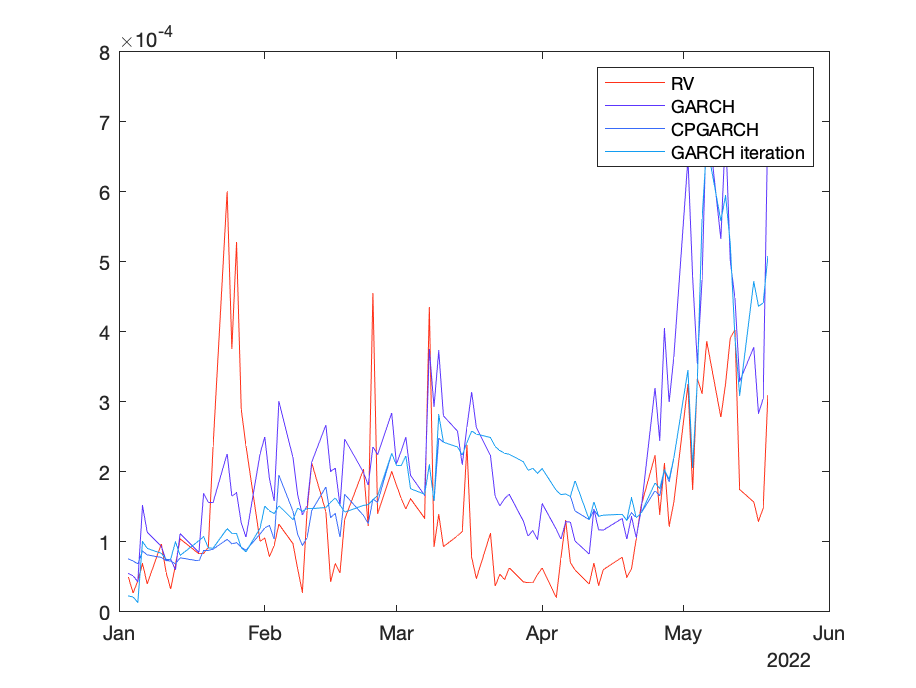

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of parameters in each estimation window

GARCH

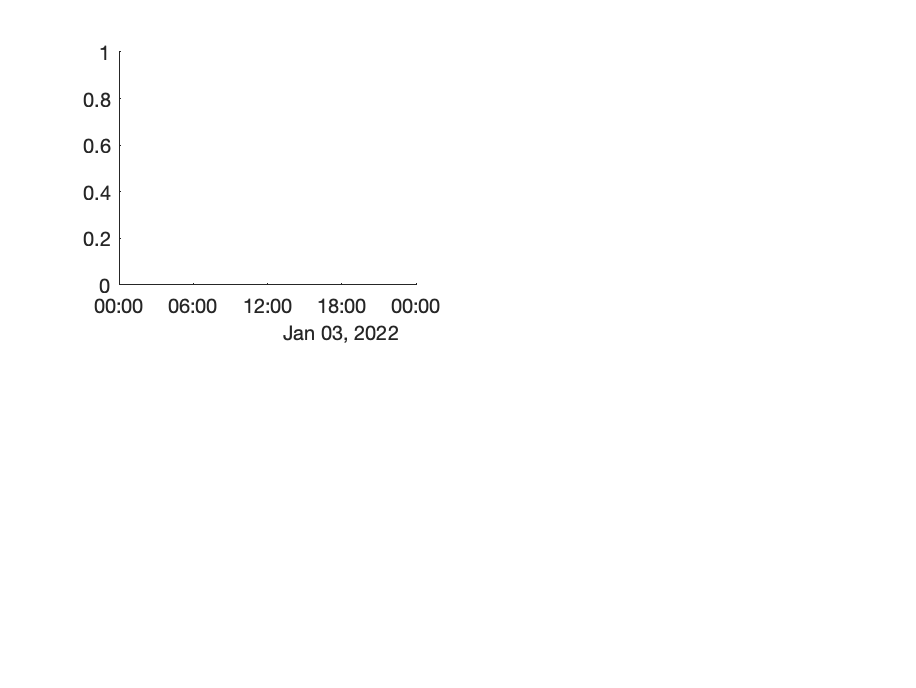

Error using plot
Vectors must be the same length.

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GARCH(:,1),"Color",col(1,:));

subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GARCH(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GARCH(:,3),"Color",col(3,:));
subtitle("GARCH")

GJR

col=rainbow(4);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GJR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GJR(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GJR(:,3),"Color",col(3,:));
subtitle("GARCH")
subplot(2,2,4);
plot(Timeline_outsample,para_GJR(:,4),"Color",col(4,:));
subtitle("Leverage")

RSGARCH

figure;
col=rainbow(2);
subplot(2,2,1);
plot(Timeline_outsample,reshape(para_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,1,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("\omega")
subplot(2,2,2);
plot(Timeline_outsample,reshape(para_RSGARCH(1,2,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("arch parameter")
subplot(2,2,3);
plot(Timeline_outsample,reshape(para_RSGARCH(1,3,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,3,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("garch parameter")
subplot(2,2,4);
plot(Timeline_outsample,reshape(transM_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(transM_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("transfer matrix")

HAR

col=rainbow(7);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,2),"Color",col(2,:));
subtitle("v_{t-1}")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,3),"Color",col(3,:));
subtitle("v_{t-5}")
subplot(2,2,4);
plot(Timeline_outsample,para_HAR(:,4),"Color",col(4,:));
subtitle("v_{t-22}")
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,5),"Color",col(5,:));
subtitle("b_J")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,6),"Color",col(6,:));
subtitle("a_1")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,7),"Color",col(7,:));
subtitle("a_2")

#### Figure of optimal cluster number in each estimation window

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJR,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### Figure of in-sample MAE and MSE

figure;
col=rainbow(12);
plot(Timeline_outsample,ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,ismae_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,ismae_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,ismae_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,ismae_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")
figure;
plot(Timeline_outsample,isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,isrmse_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,isrmse_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,isrmse_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,isrmse_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

DM test

table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJR]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJR]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### Figure of volatility persistence

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size750_20220704'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJR","vf_CPGJR","vf_CPGJRiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJR","K_RSGARCH","K_HAR", ...
    "para_HAR","para_GARCH","para_GJR","para_RSGARCH","transM_RSGARCH", ...
    "ismae_GARCH","isrmse_GARCH","ismae_CPGARCH","isrmse_CPGARCH","ismae_CPGARCHiteration","isrmse_CPGARCHiteration", ...
    "ismae_GJR","isrmse_GJR","ismae_CPGJR","isrmse_CPGJR","ismae_CPGJRiteration","isrmse_CPGJRiteration", ...
    "ismae_RSGARCH","isrmse_RSGARCH","ismae_CPRSGARCH","isrmse_CPRSGARCH","ismae_CPRSGARCHiteration","isrmse_CPRSGARCHiteration", ...
    "ismae_HAR","isrmse_HAR","ismae_CPHAR","isrmse_CPHAR","ismae_CPHARiteration","isrmse_CPHARiteration");

## FTSE

estimation window = 750

Time: 

Results: 

datatable=readtable("FTSE_0608.xlsx");
name='FTSE';
window_size = 750;
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
% volatility forecast
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_GJR=zeros(n,1);
vf_CPGJR=zeros(n,1);
vf_CPGJRiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
% in-sample fitness
ismae_GARCH=zeros(n,1);
isrmse_GARCH=zeros(n,1);
ismae_CPGARCH=zeros(n,1);
isrmse_CPGARCH=zeros(n,1);
ismae_CPGARCHiteration=zeros(n,1);
isrmse_CPGARCHiteration=zeros(n,1);
ismae_GJR=zeros(n,1);
isrmse_GJR=zeros(n,1);
ismae_CPGJR=zeros(n,1);
isrmse_CPGJR=zeros(n,1);
ismae_CPGJRiteration=zeros(n,1);
isrmse_CPGJRiteration=zeros(n,1);
ismae_RSGARCH=zeros(n,1);
isrmse_RSGARCH=zeros(n,1);
ismae_CPRSGARCH=zeros(n,1);
isrmse_CPRSGARCH=zeros(n,1);
ismae_CPRSGARCHiteration=zeros(n,1);
isrmse_CPRSGARCHiteration=zeros(n,1);
ismae_HAR=zeros(n,1);
isrmse_HAR=zeros(n,1);
ismae_CPHAR=zeros(n,1);
isrmse_CPHAR=zeros(n,1);
ismae_CPHARiteration=zeros(n,1);
isrmse_CPHARiteration=zeros(n,1);
% cluster number
K_GARCH=zeros(n,1);
K_GJR=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);
% dynamic parameter 
para_GARCH=zeros(n,3);
para_GJR=zeros(n,4);
para_RSGARCH=zeros(2,3,n);
transM_RSGARCH=zeros(2,2,n);
para_HAR=zeros(n,7);

% initial setting
i1=0;I=find(oos_index==1);

% itinial value of RSGARCH
addpath("m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[0.1 0.1 0.82;0.01 0.01 0.5];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.param_dist=[];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation,~] = swgarch(datatable.Return(I(1)-window_size:I(1)-1),Mdl_RSGARCH.k, ...
    Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
    Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
rmpath("m_Files_swgarch")

for i=I(1):I(end)
    i1=i1+1
    index=i-window_size:i-1;
    ret=datatable.Return(index);

HAR

    Jump=zeros(size(datatable.RV(index)));
    index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
    Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    para_HAR(i1,:)=paras;
    ismae_HAR(i1)=mean(abs(v_HAR-ret.^2));
    isrmse_HAR(i1)=sqrt(mean((v_HAR-ret.^2).^2));
    %% CP-HAR
    [LB,J,~]=Fisher_div_sqr(v_HAR,20);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [v_CPHAR,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHAR(i1)=mean(abs(v_CPHAR-ret.^2));
    isrmse_CPHAR(i1)=sqrt(mean((v_CPHAR-ret.^2).^2));
    %% CP-HAR-Ite.
    [v_CPHARiteration,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR, ...
        [vt_1,vt_5,vt_22,Jump,a1,a2],20);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHARiteration(i1)=mean(abs(v_CPHARiteration-ret.^2));
    isrmse_CPHARiteration(i1)=sqrt(mean((v_CPHARiteration-ret.^2).^2));

GARCH

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};
    para_GARCH(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
    ismae_GARCH(i1)=mean(abs(v_GARCH-ret.^2));
    isrmse_GARCH(i1)=sqrt(mean((v_GARCH-ret.^2).^2));
    %% CP-GARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,10);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCH(i1)=mean(abs(v_CPGARCH-ret.^2));
    isrmse_CPGARCH(i1)=sqrt(mean((v_CPGARCH-ret.^2).^2));
    %% CP-GARCH-Ite.
    [v_CPGARCHiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GARCH,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCHiteration(i1)=mean(abs(v_CPGARCHiteration-ret.^2));
    isrmse_CPGARCHiteration(i1)=sqrt(mean((v_CPGARCHiteration-ret.^2).^2));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJR = infer(EstMdl,ret);
    vf_GJR(i1)=forecast(EstMdl,1,ret);
    para_GJR(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1},EstMdl.Leverage{1}];
    ismae_GJR(i1)=mean(abs(v_GJR-ret.^2));
    isrmse_GJR(i1)=sqrt(mean((v_GJR-ret.^2).^2));
    %% CP-GJR
    [LB,J,~]=Fisher_div_sqr(v_GJR,10);
    K = OptimalClusterNumber(v_GJR,LB);
    K_GJR(i1)=K;
    [v_CPGJR,Nodes]=Vol_ClusterPartition(v_GJR,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJR(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJR(i1)=mean(abs(v_CPGJR-ret.^2));
    isrmse_CPGJR(i1)=sqrt(mean((v_CPGJR-ret.^2).^2));
    %% CP-GJR-Ite.
    [v_CPGJRiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GJR,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJRiteration(i1)=mean(abs(v_CPGJRiteration-ret.^2));
    isrmse_CPGJRiteration(i1)=sqrt(mean((v_CPGJRiteration-ret.^2).^2));

RSGARCH

    addpath("m_Files_swgarch")

    Mdl_RSGARCH.startvalG=estimation.garch;
    Mdl_RSGARCH.startvalM=estimation.transM;
    [estimation,probabilities] = swgarch(ret,Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation.garch,...
        estimation.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret,estimation.H,probabilities);
    para_RSGARCH(:,:,i1)=estimation.garch;
    transM_RSGARCH(:,:,i1)=estimation.transM;
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;
    ismae_RSGARCH(i1)=mean(abs(v_RSGARCH-ret.^2));
    isrmse_RSGARCH(i1)=sqrt(mean((v_RSGARCH-ret.^2).^2));
    %% CP-RSGARCH
    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,50);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;
    ismae_CPRSGARCH(i1)=mean(abs(v_CPRSGARCH-ret.^2));
    isrmse_CPRSGARCH(i1)=sqrt(mean((v_CPRSGARCH-ret.^2).^2));
    %% CP-RSGARCH-Ite.
    [v_CPRSGARCHiteration,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH,Mdl_RSGARCH,50);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;
    ismae_CPRSGARCHiteration(i1)=mean(abs(v_CPRSGARCHiteration-ret.^2));
    isrmse_CPRSGARCHiteration(i1)=sqrt(mean((v_CPRSGARCHiteration-ret.^2).^2));

    rmpath("m_Files_swgarch")
end

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJR, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJR, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");
set(gcf,'Position',[500 500 900 300]);

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of parameters in each estimation window

GARCH

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GARCH(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GARCH(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GARCH(:,3),"Color",col(3,:));
subtitle("GARCH")

GJR

col=rainbow(4);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GJR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GJR(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GJR(:,3),"Color",col(3,:));
subtitle("GARCH")
subplot(2,2,4);
plot(Timeline_outsample,para_GJR(:,4),"Color",col(4,:));
subtitle("Leverage")

RSGARCH

figure;
col=rainbow(2);
subplot(2,2,1);
plot(Timeline_outsample,reshape(para_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,1,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("\omega")
subplot(2,2,2);
plot(Timeline_outsample,reshape(para_RSGARCH(1,2,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("arch parameter")
subplot(2,2,3);
plot(Timeline_outsample,reshape(para_RSGARCH(1,3,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,3,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("garch parameter")
subplot(2,2,4);
plot(Timeline_outsample,reshape(transM_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(transM_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("transfer matrix")

HAR

col=rainbow(7);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,2),"Color",col(2,:));
subtitle("v_{t-1}")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,3),"Color",col(3,:));
subtitle("v_{t-5}")
subplot(2,2,4);
plot(Timeline_outsample,para_HAR(:,4),"Color",col(4,:));
subtitle("v_{t-22}")
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,5),"Color",col(5,:));
subtitle("b_J")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,6),"Color",col(6,:));
subtitle("a_1")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,7),"Color",col(7,:));
subtitle("a_2")

#### Figure of optimal cluster number in each estimation window

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJR,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### Figure of in-sample MAE and MSE

figure;
col=rainbow(12);
plot(Timeline_outsample,ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,ismae_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,ismae_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,ismae_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,ismae_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")
figure;
plot(Timeline_outsample,isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,isrmse_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,isrmse_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,isrmse_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,isrmse_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

DM test

table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJR]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJR]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### Figure of volatility persistence

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size750_20220704'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJR","vf_CPGJR","vf_CPGJRiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJR","K_RSGARCH","K_HAR", ...
    "para_HAR","para_GARCH","para_GJR","para_RSGARCH","transM_RSGARCH", ...
    "ismae_GARCH","isrmse_GARCH","ismae_CPGARCH","isrmse_CPGARCH","ismae_CPGARCHiteration","isrmse_CPGARCHiteration", ...
    "ismae_GJR","isrmse_GJR","ismae_CPGJR","isrmse_CPGJR","ismae_CPGJRiteration","isrmse_CPGJRiteration", ...
    "ismae_RSGARCH","isrmse_RSGARCH","ismae_CPRSGARCH","isrmse_CPRSGARCH","ismae_CPRSGARCHiteration","isrmse_CPRSGARCHiteration", ...
    "ismae_HAR","isrmse_HAR","ismae_CPHAR","isrmse_CPHAR","ismae_CPHARiteration","isrmse_CPHARiteration");

## NIKKIE

estimation window = 750

Time: 

Results: 

datatable=readtable("NIKKIE_0608.xlsx");
name='NIKKIE';
window_size = 750;
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
% volatility forecast
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJR=zeros(n,1);
vf_CPGJR=zeros(n,1);
vf_CPGJRiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
% in-sample fitness
ismae_GARCH=zeros(n,1);
isrmse_GARCH=zeros(n,1);
ismae_CPGARCH=zeros(n,1);
isrmse_CPGARCH=zeros(n,1);
ismae_CPGARCHiteration=zeros(n,1);
isrmse_CPGARCHiteration=zeros(n,1);
ismae_GJR=zeros(n,1);
isrmse_GJR=zeros(n,1);
ismae_CPGJR=zeros(n,1);
isrmse_CPGJR=zeros(n,1);
ismae_CPGJRiteration=zeros(n,1);
isrmse_CPGJRiteration=zeros(n,1);
ismae_RSGARCH=zeros(n,1);
isrmse_RSGARCH=zeros(n,1);
ismae_CPRSGARCH=zeros(n,1);
isrmse_CPRSGARCH=zeros(n,1);
ismae_CPRSGARCHiteration=zeros(n,1);
isrmse_CPRSGARCHiteration=zeros(n,1);
ismae_HAR=zeros(n,1);
isrmse_HAR=zeros(n,1);
ismae_CPHAR=zeros(n,1);
isrmse_CPHAR=zeros(n,1);
ismae_CPHARiteration=zeros(n,1);
isrmse_CPHARiteration=zeros(n,1);
% cluster number
K_GARCH=zeros(n,1);
K_EGARCH=zeros(n,1);
K_GJR=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);
% dynamic parameter 
para_GARCH=zeros(n,3);
para_GJR=zeros(n,4);
para_RSGARCH=zeros(2,3,n);
transM_RSGARCH=zeros(2,2,n);
para_HAR=zeros(n,7);

% initial setting
i1=0;I=find(oos_index==1);

% itinial value of RSGARCH
addpath("m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[0.1 0.1 0.82;0.01 0.01 0.5];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.param_dist=[];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
[estimation,probabilities] = swgarch(datatable.Return(I(1)-window_size:I(1)-1),Mdl_RSGARCH.k, ...
    Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
    Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
rmpath("m_Files_swgarch")

for i=I(1):I(end)
    i1=i1+1
    index=i-window_size:i-1;
    ret=datatable.Return(index);

HAR

    Jump=zeros(size(datatable.RV(index)));
    index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
    Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    para_HAR(i1,:)=paras;
    ismae_HAR(i1)=mean(abs(v_HAR-ret.^2));
    isrmse_HAR(i1)=sqrt(mean((v_HAR-ret.^2).^2));
    %% CP-HAR
    [LB,J,~]=Fisher_div_sqr(v_HAR,20);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [v_CPHAR,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHAR(i1)=mean(abs(v_CPHAR-ret.^2));
    isrmse_CPHAR(i1)=sqrt(mean((v_CPHAR-ret.^2).^2));
    %% CP-HAR-Ite.
    [v_CPHARiteration,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR, ...
        [vt_1,vt_5,vt_22,Jump,a1,a2],20);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);
    ismae_CPHARiteration(i1)=mean(abs(v_CPHARiteration-ret.^2));
    isrmse_CPHARiteration(i1)=sqrt(mean((v_CPHARiteration-ret.^2).^2));

GARCH

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};
    para_GARCH(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
    ismae_GARCH(i1)=mean(abs(v_GARCH-ret.^2));
    isrmse_GARCH(i1)=sqrt(mean((v_GARCH-ret.^2).^2));
    %% CP-GARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,10);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCH(i1)=mean(abs(v_CPGARCH-ret.^2));
    isrmse_CPGARCH(i1)=sqrt(mean((v_CPGARCH-ret.^2).^2));
    %% CP-GARCH-Ite.
    [v_CPGARCHiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GARCH,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGARCHiteration(i1)=mean(abs(v_CPGARCHiteration-ret.^2));
    isrmse_CPGARCHiteration(i1)=sqrt(mean((v_CPGARCHiteration-ret.^2).^2));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJR = infer(EstMdl,ret);
    vf_GJR(i1)=forecast(EstMdl,1,ret);
    para_GJR(i1,:)=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1},EstMdl.Leverage{1}];
    ismae_GJR(i1)=mean(abs(v_GJR-ret.^2));
    isrmse_GJR(i1)=sqrt(mean((v_GJR-ret.^2).^2));
    %% CP-GJR
    [LB,J,~]=Fisher_div_sqr(v_GJR,10);
    K = OptimalClusterNumber(v_GJR,LB);
    K_GJR(i1)=K;
    [v_CPGJR,Nodes]=Vol_ClusterPartition(v_GJR,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJR(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJR(i1)=mean(abs(v_CPGJR-ret.^2));
    isrmse_CPGJR(i1)=sqrt(mean((v_CPGJR-ret.^2).^2));
    %% CP-GJR-Ite.
    [v_CPGJRiteration,Nodes] = Vol_ClusterPartitionIterationModel(Nodes,ret,v_GJR,Mdl);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));
    ismae_CPGJRiteration(i1)=mean(abs(v_CPGJRiteration-ret.^2));
    isrmse_CPGJRiteration(i1)=sqrt(mean((v_CPGJRiteration-ret.^2).^2));

RSGARCH

    addpath("m_Files_swgarch")

    Mdl_RSGARCH.startvalG=estimation.garch;
    Mdl_RSGARCH.startvalM=estimation.transM;
    [estimation,probabilities] = swgarch(ret,Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation.garch,...
        estimation.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret,estimation.H,probabilities);
    para_RSGARCH(:,:,i1)=estimation.garch;
    transM_RSGARCH(:,:,i1)=estimation.transM;
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;
    ismae_RSGARCH(i1)=mean(abs(v_RSGARCH-ret.^2));
    isrmse_RSGARCH(i1)=sqrt(mean((v_RSGARCH-ret.^2).^2));
    %% CP-RSGARCH
    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,50);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;
    ismae_CPRSGARCH(i1)=mean(abs(v_CPRSGARCH-ret.^2));
    isrmse_CPRSGARCH(i1)=sqrt(mean((v_CPRSGARCH-ret.^2).^2));
    %% CP-RSGARCH-Ite.
    [v_CPRSGARCHiteration,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH,Mdl_RSGARCH,50);
    [estimation_last,probabilities] = swgarch(ret(Nodes(end):end),Mdl_RSGARCH.k, ...
        Mdl_RSGARCH.innovation,Mdl_RSGARCH.model,Mdl_RSGARCH.constraint, ...
        Mdl_RSGARCH.startvalopt,Mdl_RSGARCH.startvalG,Mdl_RSGARCH.startvalM);
    datafcst = swgarch_forecast(1,Mdl_RSGARCH.k,estimation_last.garch,...
        estimation_last.transM,Mdl_RSGARCH.dep_type,Mdl_RSGARCH.innovation,Mdl_RSGARCH.param_dist, ...
        Mdl_RSGARCH.fig,ret(Nodes(end):end),estimation_last.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;
    ismae_CPRSGARCHiteration(i1)=mean(abs(v_CPRSGARCHiteration-ret.^2));
    isrmse_CPRSGARCHiteration(i1)=sqrt(mean((v_CPRSGARCHiteration-ret.^2).^2));

    rmpath("m_Files_swgarch")
end

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJR, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJR, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");
set(gcf,'Position',[500 500 900 300]);

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of parameters in each estimation window

GARCH

col=rainbow(3);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GARCH(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GARCH(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GARCH(:,3),"Color",col(3,:));
subtitle("GARCH")

GJR

col=rainbow(4);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_GJR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_GJR(:,2),"Color",col(2,:));
subtitle("ARCH")
subplot(2,2,3);
plot(Timeline_outsample,para_GJR(:,3),"Color",col(3,:));
subtitle("GARCH")
subplot(2,2,4);
plot(Timeline_outsample,para_GJR(:,4),"Color",col(4,:));
subtitle("Leverage")

RSGARCH

figure;
col=rainbow(2);
subplot(2,2,1);
plot(Timeline_outsample,reshape(para_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,1,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("\omega")
subplot(2,2,2);
plot(Timeline_outsample,reshape(para_RSGARCH(1,2,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("arch parameter")
subplot(2,2,3);
plot(Timeline_outsample,reshape(para_RSGARCH(1,3,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(para_RSGARCH(2,3,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("garch parameter")
subplot(2,2,4);
plot(Timeline_outsample,reshape(transM_RSGARCH(1,1,:),n,1),"Color",col(1,:));hold on
plot(Timeline_outsample,reshape(transM_RSGARCH(2,2,:),n,1),"Color",col(2,:));
legend("Regime 1","Regime 2")
subtitle("transfer matrix")

HAR

col=rainbow(7);
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,1),"Color",col(1,:));
subtitle("constant")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,2),"Color",col(2,:));
subtitle("v_{t-1}")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,3),"Color",col(3,:));
subtitle("v_{t-5}")
subplot(2,2,4);
plot(Timeline_outsample,para_HAR(:,4),"Color",col(4,:));
subtitle("v_{t-22}")
figure;
subplot(2,2,1);
plot(Timeline_outsample,para_HAR(:,5),"Color",col(5,:));
subtitle("b_J")
subplot(2,2,2);
plot(Timeline_outsample,para_HAR(:,6),"Color",col(6,:));
subtitle("a_1")
subplot(2,2,3);
plot(Timeline_outsample,para_HAR(:,7),"Color",col(7,:));
subtitle("a_2")

#### Figure of optimal cluster number in each estimation window

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJR,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### Figure of in-sample MAE and MSE

figure;
col=rainbow(12);
plot(Timeline_outsample,ismae_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,ismae_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,ismae_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,ismae_GJR,"Color",col(4,:));
plot(Timeline_outsample,ismae_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,ismae_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,ismae_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,ismae_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,ismae_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,ismae_HAR,"Color",col(10,:));
plot(Timeline_outsample,ismae_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,ismae_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")
figure;
plot(Timeline_outsample,isrmse_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,isrmse_CPGARCH,"Color",col(2,:));
plot(Timeline_outsample,isrmse_CPGARCHiteration,"Color",col(3,:));
plot(Timeline_outsample,isrmse_GJR,"Color",col(4,:));
plot(Timeline_outsample,isrmse_CPGJR,"Color",col(5,:));
plot(Timeline_outsample,isrmse_CPGJRiteration,"Color",col(6,:));
plot(Timeline_outsample,isrmse_RSGARCH,"Color",col(7,:));
plot(Timeline_outsample,isrmse_CPRSGARCH,"Color",col(8,:));
plot(Timeline_outsample,isrmse_CPRSGARCHiteration,"Color",col(9,:));
plot(Timeline_outsample,isrmse_HAR,"Color",col(10,:));
plot(Timeline_outsample,isrmse_CPHAR,"Color",col(11,:));
plot(Timeline_outsample,isrmse_CPHARiteration,"Color",col(12,:));
legend("GARCH","CPGARCH","CPGARCH Ite.", ...
    "GJR","CPGJR","CPGJR Ite.", ...
    "RSGARCH","CPRSGARCH","CPRSGARCH Ite.", ...
    "HAR","CPHAR","CPHAR Ite.")
title("in-sample MAE")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJR-rv));mean(abs(vf_CPGJR-rv));mean(abs(vf_CPGJRiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJR-rv).^2);mean((vf_CPGJR-rv).^2);mean((vf_CPGJRiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

DM test

table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJR]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJR]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

#### Figure of volatility persistence

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size750_20220704'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJR","vf_CPGJR","vf_CPGJRiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJR","K_RSGARCH","K_HAR", ...
    "para_HAR","para_GARCH","para_GJR","para_RSGARCH","transM_RSGARCH", ...
    "ismae_GARCH","isrmse_GARCH","ismae_CPGARCH","isrmse_CPGARCH","ismae_CPGARCHiteration","isrmse_CPGARCHiteration", ...
    "ismae_GJR","isrmse_GJR","ismae_CPGJR","isrmse_CPGJR","ismae_CPGJRiteration","isrmse_CPGJRiteration", ...
    "ismae_RSGARCH","isrmse_RSGARCH","ismae_CPRSGARCH","isrmse_CPRSGARCH","ismae_CPRSGARCHiteration","isrmse_CPRSGARCHiteration", ...
    "ismae_HAR","isrmse_HAR","ismae_CPHAR","isrmse_CPHAR","ismae_CPHARiteration","isrmse_CPHARiteration");

function DM = dmtest(e1, e2, h)
if nargin < 2
    error('dmtest:TooFewInputs','At least two arguments are required');
end
if nargin < 3
    h = 1;
end
if size(e1,1) ~= size(e2,1) || size(e1,2) ~= size(e2,2)
    error('dmtest:InvalidInput','Vectors should be of equal length');
end
if size(e1,2) > 1 || size(e2,2) > 1
    error('dmtest:InvalidInput','Input should have T rows and 1 column');
end
% Initialization
T = size(e1,1);
% Define the loss differential
d = e1.^2 - e2.^2;
dMean = mean(d);
gamma0 = var(d);
if h > 1
    gamma = zeros(h-1,1);
    for i = 1:h-1
        gamma(i) = ( d(1+i:T)' * d(1:T-i) ) ./ T; % bugfix
    end
    varD = gamma0 + 2*sum(gamma);
else
    varD = gamma0;
end
DM = dMean / sqrt ( (1/T)*varD );
end

function [LB,J,D] = Fisher_div_sqr(sigma2,h,D)
T = numel(sigma2);
if T<100000
    if nargin < 3
        D = zeros(T,T);  %计算直径
        for i = 1 : T
            strcat('D:',num2str(i));
            for j = i : T
                D(i,j) = sum(    (    sigma2(i:j) - mean(sigma2(i:j)) ).^2            );
                %                 D(i,j) = (std(sigma2(i:j))*(j-i+1)).^2;
            end
        end
        for i = 1 : T
            for j = 1 : i
                D(i,j) = D(j,i);
            end
        end
    else
        if length(sigma2)==length(D)
            D(1:end-1,1:end-1)=D(2:end,2:end);
            for i = 1 : T
                D(i,end)=sum((sigma2(i:end)-mean(sigma2(i:end)).^2));
            end
            D(end,:)=D(:,end)';
        else
            warning('Size of Distance matrix and length of sigma2 do not match.')
        end
    end
    % LB = zeros(T,T); % 最优损失函数
    % J = ones(T,T);   % 对LP(n,k)分割，最后一个分割点
    LB = nan(T,min(T,floor(T/h))-1); % 最优损失函数
    J = nan(T,min(T,floor(T/h))-1);   % 对LP(n,k)分割，最后一个分割点
    for k = 2 : min(T,floor(T/h))-1 % 分类数k，从二分类开始，最多到floor(T/h)-1分类
        for n = h*k : T % 样本数量n至少为h*k个，最多是T个
            minLP = 10^300;
            strcat('k:',num2str(k),' n:',num2str(n));
            if k == 2
                for j = h*(k-1)+1 : n-h+1 % 分割点j，从h*(k-1)+1开始找，找至n-h+1
                    d = D(1,j-1)+D(j,n);
                    if d < minLP
                        minLP = d;
                        minJ = j;
                    end
                end
            else
                for j = h*(k-1)+1 : n-h+1
                    d = LB(j-1,k-1) + D(j,n);
                    if d < minLP
                        minLP = d;
                        minJ = j;
                    end
                end
            end
            LB(n,k) = minLP;
            J(n,k) = minJ;
        end
    end
    
else
    LB = nan(T,min(T,floor(T/h))-1); % 最优损失函数
    J = nan(T,min(T,floor(T/h))-1);   % 对LP(n,k)分割，最后一个分割点
    for k = 2 : min(T,floor(T/h))-1 % 分类数k，从二分类开始，最多到floor(T/h)-1分类
        for n = h*k : T % 样本数量n至少为h*k个，最多是T个
            minLP = 10^300;
            strcat('k:',num2str(k),' n:',num2str(n));
            if k == 2
                for j = h*(k-1)+1 : n-h+1 % 分割点j，从h*(k-1)+1开始找，找至n-h+1
                    %                     d = std(sigma2(1:j-1))*(j-1)+std(sigma2(j:n))*(n-j+1);
                    d = sum( ( sigma2(1:j-1) - mean(sigma2(1:j-1)) ).^2 )...
                        +sum( ( sigma2(j:n) - mean(sigma2(j:n)) ).^2 );
                    if d < minLP
                        minLP = d;
                        minJ = j;
                    end
                end
            else
                for j = h*(k-1)+1 : n-h+1
                    d = LB(j-1,k-1) + sum( ( sigma2(j:n) - mean(sigma2(j:n)) ).^2 );
                    %                     d = LB(j-1,k-1) + std(sigma2(j:n))*(n-j+1);
                    if d < minLP
                        minLP = d;
                        minJ = j;
                    end
                end
            end
            LB(n,k) = minLP;
            J(n,k) = minJ;
        end
    end
end
J(:,1) = 1;
end

function N = OptimalClusterNumber(sigma,LB)
N=size(LB,2);y=zeros(N,1);
for k = 2:N
    y(k)=log(numel(sigma))*k/numel(sigma) + log(LB(numel(sigma),k)/numel(sigma));
end
N=find(y==min(y(2:end)),1)+1;
end

function map = rainbow(N)
if nargin<1 || isempty(N)
	N = size(get(gcf,'colormap'),1);
else
	assert(isscalar(N)&&isreal(N),'First argument must be a real numeric scalar.')
end
C = [0.498039215686275,0,1;0.490196078431373,0.0117647058823529,0.996078431372549;0.486274509803922,0.0196078431372549,0.996078431372549;0.474509803921569,0.0352941176470588,0.996078431372549;0.466666666666667,0.0470588235294118,0.996078431372549;0.458823529411765,0.0588235294117647,0.996078431372549;0.450980392156863,0.0705882352941177,0.996078431372549;0.443137254901961,0.0823529411764706,0.996078431372549;0.435294117647059,0.0980392156862745,0.996078431372549;0.427450980392157,0.109803921568627,0.996078431372549;0.419607843137255,0.121568627450980,0.996078431372549;0.411764705882353,0.133333333333333,0.996078431372549;0.403921568627451,0.145098039215686,0.996078431372549;0.392156862745098,0.160784313725490,0.996078431372549;0.388235294117647,0.168627450980392,0.996078431372549;0.372549019607843,0.192156862745098,0.992156862745098;0.372549019607843,0.196078431372549,0.992156862745098;0.356862745098039,0.219607843137255,0.992156862745098;0.349019607843137,0.227450980392157,0.992156862745098;0.349019607843137,0.231372549019608,0.992156862745098;0.333333333333333,0.254901960784314,0.988235294117647;0.329411764705882,0.258823529411765,0.988235294117647;0.317647058823529,0.278431372549020,0.988235294117647;0.309803921568627,0.290196078431373,0.988235294117647;0.301960784313725,0.301960784313725,0.984313725490196;0.294117647058824,0.313725490196078,0.984313725490196;0.286274509803922,0.321568627450980,0.984313725490196;0.278431372549020,0.337254901960784,0.984313725490196;0.270588235294118,0.349019607843137,0.980392156862745;0.262745098039216,0.360784313725490,0.980392156862745;0.254901960784314,0.372549019607843,0.980392156862745;0.247058823529412,0.380392156862745,0.980392156862745;0.239215686274510,0.396078431372549,0.976470588235294;0.231372549019608,0.403921568627451,0.976470588235294;0.223529411764706,0.415686274509804,0.976470588235294;0.215686274509804,0.427450980392157,0.972549019607843;0.207843137254902,0.439215686274510,0.972549019607843;0.196078431372549,0.454901960784314,0.968627450980392;0.192156862745098,0.458823529411765,0.968627450980392;0.176470588235294,0.482352941176471,0.964705882352941;0.176470588235294,0.486274509803922,0.964705882352941;0.160784313725490,0.501960784313726,0.964705882352941;0.152941176470588,0.513725490196078,0.960784313725490;0.152941176470588,0.513725490196078,0.960784313725490;0.137254901960784,0.533333333333333,0.956862745098039;0.133333333333333,0.541176470588235,0.956862745098039;0.121568627450980,0.556862745098039,0.952941176470588;0.113725490196078,0.564705882352941,0.952941176470588;0.105882352941176,0.576470588235294,0.952941176470588;0.0980392156862745,0.584313725490196,0.949019607843137;0.0901960784313726,0.596078431372549,0.949019607843137;0.0823529411764706,0.603921568627451,0.945098039215686;0.0745098039215686,0.615686274509804,0.945098039215686;0.0666666666666667,0.623529411764706,0.941176470588235;0.0588235294117647,0.635294117647059,0.937254901960784;0.0509803921568627,0.643137254901961,0.937254901960784;0.0392156862745098,0.658823529411765,0.933333333333333;0.0352941176470588,0.662745098039216,0.933333333333333;0.0274509803921569,0.670588235294118,0.929411764705882;0.0196078431372549,0.682352941176471,0.929411764705882;0.0117647058823529,0.690196078431373,0.925490196078431;0,0.701960784313725,0.921568627450980;0,0.705882352941177,0.921568627450980;0.0156862745098039,0.725490196078431,0.917647058823529;0.0196078431372549,0.729411764705882,0.917647058823529;0.0313725490196078,0.741176470588235,0.909803921568627;0.0392156862745098,0.749019607843137,0.909803921568627;0.0392156862745098,0.749019607843137,0.909803921568627;0.0549019607843137,0.764705882352941,0.901960784313726;0.0588235294117647,0.768627450980392,0.901960784313726;0.0705882352941177,0.780392156862745,0.898039215686275;0.0784313725490196,0.788235294117647,0.894117647058824;0.0862745098039216,0.796078431372549,0.894117647058824;0.0941176470588235,0.803921568627451,0.890196078431373;0.101960784313725,0.811764705882353,0.886274509803922;0.109803921568627,0.819607843137255,0.886274509803922;0.117647058823529,0.823529411764706,0.882352941176471;0.125490196078431,0.831372549019608,0.878431372549020;0.133333333333333,0.839215686274510,0.874509803921569;0.141176470588235,0.843137254901961,0.874509803921569;0.152941176470588,0.854901960784314,0.870588235294118;0.156862745098039,0.858823529411765,0.866666666666667;0.164705882352941,0.862745098039216,0.862745098039216;0.172549019607843,0.870588235294118,0.862745098039216;0.180392156862745,0.874509803921569,0.858823529411765;0.192156862745098,0.886274509803922,0.850980392156863;0.196078431372549,0.886274509803922,0.850980392156863;0.211764705882353,0.898039215686275,0.843137254901961;0.215686274509804,0.898039215686275,0.843137254901961;0.227450980392157,0.909803921568627,0.839215686274510;0.235294117647059,0.913725490196078,0.835294117647059;0.235294117647059,0.913725490196078,0.835294117647059;0.250980392156863,0.925490196078431,0.827450980392157;0.258823529411765,0.929411764705882,0.823529411764706;0.266666666666667,0.933333333333333,0.819607843137255;0.274509803921569,0.937254901960784,0.819607843137255;0.282352941176471,0.941176470588235,0.815686274509804;0.290196078431373,0.945098039215686,0.811764705882353;0.298039215686275,0.949019607843137,0.807843137254902;0.305882352941177,0.952941176470588,0.803921568627451;0.313725490196078,0.956862745098039,0.800000000000000;0.321568627450980,0.960784313725490,0.796078431372549;0.329411764705882,0.964705882352941,0.792156862745098;0.337254901960784,0.964705882352941,0.788235294117647;0.349019607843137,0.972549019607843,0.780392156862745;0.352941176470588,0.972549019607843,0.780392156862745;0.368627450980392,0.976470588235294,0.772549019607843;0.368627450980392,0.976470588235294,0.772549019607843;0.376470588235294,0.980392156862745,0.768627450980392;0.392156862745098,0.984313725490196,0.760784313725490;0.392156862745098,0.984313725490196,0.760784313725490;0.407843137254902,0.988235294117647,0.752941176470588;0.411764705882353,0.988235294117647,0.749019607843137;0.423529411764706,0.992156862745098,0.745098039215686;0.431372549019608,0.992156862745098,0.741176470588235;0.431372549019608,0.992156862745098,0.741176470588235;0.447058823529412,0.996078431372549,0.733333333333333;0.454901960784314,0.996078431372549,0.729411764705882;0.462745098039216,0.996078431372549,0.725490196078431;0.470588235294118,0.996078431372549,0.721568627450980;0.478431372549020,0.996078431372549,0.717647058823529;0.486274509803922,0.996078431372549,0.709803921568628;0.494117647058824,0.996078431372549,0.705882352941177;0.501960784313726,0.996078431372549,0.701960784313725;0.509803921568627,0.996078431372549,0.698039215686275;0.517647058823530,0.996078431372549,0.694117647058824;0.525490196078431,0.996078431372549,0.690196078431373;0.533333333333333,0.996078431372549,0.686274509803922;0.545098039215686,0.996078431372549,0.678431372549020;0.549019607843137,0.996078431372549,0.674509803921569;0.564705882352941,0.992156862745098,0.666666666666667;0.568627450980392,0.992156862745098,0.666666666666667;0.572549019607843,0.992156862745098,0.662745098039216;0.588235294117647,0.988235294117647,0.654901960784314;0.588235294117647,0.988235294117647,0.654901960784314;0.603921568627451,0.984313725490196,0.643137254901961;0.607843137254902,0.980392156862745,0.639215686274510;0.619607843137255,0.980392156862745,0.635294117647059;0.627450980392157,0.976470588235294,0.631372549019608;0.635294117647059,0.976470588235294,0.623529411764706;0.643137254901961,0.972549019607843,0.619607843137255;0.650980392156863,0.968627450980392,0.615686274509804;0.658823529411765,0.964705882352941,0.611764705882353;0.666666666666667,0.964705882352941,0.603921568627451;0.674509803921569,0.960784313725490,0.600000000000000;0.682352941176471,0.956862745098039,0.596078431372549;0.690196078431373,0.952941176470588,0.592156862745098;0.698039215686275,0.949019607843137,0.584313725490196;0.705882352941177,0.945098039215686,0.580392156862745;0.713725490196078,0.941176470588235,0.576470588235294;0.721568627450980,0.937254901960784,0.572549019607843;0.729411764705882,0.933333333333333,0.564705882352941;0.741176470588235,0.925490196078431,0.556862745098039;0.745098039215686,0.925490196078431,0.556862745098039;0.760784313725490,0.913725490196078,0.545098039215686;0.764705882352941,0.913725490196078,0.545098039215686;0.768627450980392,0.909803921568627,0.541176470588235;0.784313725490196,0.898039215686275,0.529411764705882;0.784313725490196,0.898039215686275,0.529411764705882;0.800000000000000,0.886274509803922,0.517647058823530;0.803921568627451,0.882352941176471,0.513725490196078;0.815686274509804,0.874509803921569,0.509803921568627;0.823529411764706,0.870588235294118,0.501960784313726;0.831372549019608,0.862745098039216,0.498039215686275;0.839215686274510,0.858823529411765,0.494117647058824;0.847058823529412,0.850980392156863,0.486274509803922;0.854901960784314,0.843137254901961,0.482352941176471;0.862745098039216,0.839215686274510,0.478431372549020;0.870588235294118,0.831372549019608,0.470588235294118;0.878431372549020,0.823529411764706,0.466666666666667;0.886274509803922,0.819607843137255,0.458823529411765;0.894117647058824,0.811764705882353,0.454901960784314;0.901960784313726,0.803921568627451,0.450980392156863;0.909803921568627,0.796078431372549,0.443137254901961;0.917647058823529,0.788235294117647,0.439215686274510;0.925490196078431,0.780392156862745,0.431372549019608;0.941176470588235,0.764705882352941,0.423529411764706;0.941176470588235,0.764705882352941,0.423529411764706;0.956862745098039,0.749019607843137,0.411764705882353;0.960784313725490,0.745098039215686,0.407843137254902;0.964705882352941,0.741176470588235,0.403921568627451;0.980392156862745,0.725490196078431,0.392156862745098;0.980392156862745,0.725490196078431,0.392156862745098;0.996078431372549,0.705882352941177,0.380392156862745;1,0.698039215686275,0.376470588235294;1,0.690196078431373,0.372549019607843;1,0.682352941176471,0.364705882352941;1,0.670588235294118,0.360784313725490;1,0.662745098039216,0.352941176470588;1,0.654901960784314,0.349019607843137;1,0.643137254901961,0.341176470588235;1,0.635294117647059,0.337254901960784;1,0.623529411764706,0.329411764705882;1,0.615686274509804,0.325490196078431;1,0.603921568627451,0.317647058823529;1,0.588235294117647,0.309803921568627;1,0.584313725490196,0.305882352941177;1,0.576470588235294,0.301960784313725;1,0.560784313725490,0.294117647058824;1,0.556862745098039,0.290196078431373;1,0.533333333333333,0.278431372549020;1,0.533333333333333,0.278431372549020;1,0.513725490196078,0.266666666666667;1,0.505882352941176,0.262745098039216;1,0.501960784313726,0.258823529411765;1,0.482352941176471,0.247058823529412;1,0.478431372549020,0.247058823529412;1,0.458823529411765,0.235294117647059;1,0.450980392156863,0.231372549019608;1,0.439215686274510,0.223529411764706;1,0.427450980392157,0.219607843137255;1,0.415686274509804,0.211764705882353;1,0.403921568627451,0.207843137254902;1,0.392156862745098,0.200000000000000;1,0.380392156862745,0.192156862745098;1,0.372549019607843,0.188235294117647;1,0.360784313725490,0.180392156862745;1,0.349019607843137,0.176470588235294;1,0.337254901960784,0.168627450980392;1,0.317647058823529,0.160784313725490;1,0.313725490196078,0.156862745098039;1,0.301960784313725,0.152941176470588;1,0.286274509803922,0.145098039215686;1,0.278431372549020,0.141176470588235;1,0.254901960784314,0.125490196078431;1,0.254901960784314,0.125490196078431;1,0.231372549019608,0.113725490196078;1,0.223529411764706,0.109803921568627;1,0.219607843137255,0.109803921568627;1,0.192156862745098,0.0980392156862745;1,0.188235294117647,0.0941176470588235;1,0.168627450980392,0.0823529411764706;1,0.156862745098039,0.0784313725490196;1,0.145098039215686,0.0705882352941177;1,0.133333333333333,0.0666666666666667;1,0.121568627450980,0.0588235294117647;1,0.109803921568627,0.0549019607843137;1,0.0980392156862745,0.0470588235294118;1,0.0823529411764706,0.0392156862745098;1,0.0705882352941177,0.0352941176470588;1,0.0588235294117647,0.0274509803921569;1,0.0470588235294118,0.0235294117647059;1,0.0352941176470588,0.0156862745098039;1,0.0156862745098039,0.00392156862745098;1,0.0117647058823529,0.00392156862745098;1,0,0;1,0,0];
num = size(C,1);
vec = linspace(0,num+1,N+2);
map = interp1(1:num,C,vec(2:end-1),'linear','extrap'); %...插值
map = max(0,min(1,map));
end

function [sigma_hat,Nodes,TimeTable] = Vol_ClusterPartition(sigma,K,J,Time)
% K:聚类数
T = numel(sigma);
Nodes = ones(K,1);
n = T;
if K>=n
    warning("Cluster number should be smaller than data size")
end
for i = K : -1 : 1
    Nodes(i) = J(n,i);
    n = Nodes(i) - 1;
end
sigma_hat = sigma;
for i = 1 : K-1
    sigma_hat(Nodes(i):Nodes(i+1)-1)=mean( sigma(Nodes(i):Nodes(i+1)-1) );
end
sigma_hat(Nodes(K):end)=mean( sigma(Nodes(K):end) );
if nargin>3
    %     TimeTable = zeros(K,3); % 每个聚类节点的时间
    %     for i = 1 : K
    %         TimeTable(i,:) = Time(Nodes(i),:);
    %     end
    TimeTable = cell(K,1); % 每个聚类节点的时间
    for i = 1 : K
        TimeTable{i,1} = datestr(Time(Nodes(i),:));
    end
else
    TimeTable=[];
end
end

function [rv_iterated,Nodes_iterated] = Vol_ClusterPartitionIterationHAR(Nodes_initial,vt,rv_est,X,h)
if nargin<=4
    h = 20;
end
rv_PieceHAR = zeros(size(vt));
for i1 = 1 : numel(Nodes_initial)-1
    index=Nodes_initial(i1):Nodes_initial(i1+1)-1;
    if Nodes_initial(i1+1)-Nodes_initial(i1)>=10
        rv_PieceHAR(index) = Vol_HAR(vt(index),X(index,:));
    else
        rv_PieceHAR(index) = rv_est(index);
    end
end
N = Nodes_initial(end);
if numel(vt)-N>=10
    rv_PieceHAR(N:end) = Vol_HAR(vt(N:end),X(N:end,:));
else
    rv_PieceHAR(N:end) = rv_est(N:end);
end
% 分段GARCH波动率聚类分割
[LB_iterated,J_iterated,~] = Fisher_div_sqr(rv_PieceHAR,h);
K_iterated = OptimalClusterNumber(rv_PieceHAR,LB_iterated);% 确定最优分类数
[rv_iterated,Nodes_iterated] = Vol_ClusterPartition(rv_PieceHAR,K_iterated,J_iterated);
% 迭代过程
IterationTime = 0;
while ~isequal(Nodes_initial,Nodes_iterated) && IterationTime<100
    IterationTime = IterationTime + 1;
    Nodes_initial = Nodes_iterated;
    rv_PieceHAR = zeros(size(vt));
    for i1 = 1 : numel(Nodes_initial)-1
        index=Nodes_initial(i1):Nodes_initial(i1+1)-1;
        if Nodes_initial(i1+1)-Nodes_initial(i1)>=10
            rv_PieceHAR(index) = Vol_HAR(vt(index),X(index,:));
        else
            rv_PieceHAR(index) = rv_est(index);
        end
    end
    N = Nodes_initial(end);
    if numel(vt)-Nodes_initial(end)>=h
        rv_PieceHAR(N:end) = Vol_HAR(vt(N:end),X(N:end,:));
    else
        rv_PieceHAR(N:end) = rv_est(N:end);
    end
    [LB_iterated,J_iterated,~] = Fisher_div_sqr(rv_PieceHAR,h);
    K_iterated = OptimalClusterNumber(rv_PieceHAR,LB_iterated);% 确定最优分类数
    [rv_iterated,Nodes_iterated] = Vol_ClusterPartition(rv_PieceHAR,K_iterated,J_iterated);
end
end

function [sigma2_iterated,Nodes_iterated] = Vol_ClusterPartitionIterationModel(Nodes_initial,logRet,sigma2,Mdl,h)
if nargin<=4
    h = 10;
end
% 参数设置
% T = length(logRet);
% 分段GARCH波动率
sigma2_PieceGARCH = zeros(size(logRet));
for i1 = 1 : numel(Nodes_initial)-1
    if Nodes_initial(i1+1)-Nodes_initial(i1)>=h
        EstMdl = estimate(Mdl,logRet(Nodes_initial(i1):Nodes_initial(i1+1)-1),"Display","off");
        sigma2_PieceGARCH(Nodes_initial(i1):Nodes_initial(i1+1)-1) = ...
            infer(EstMdl,logRet(Nodes_initial(i1):Nodes_initial(i1+1)-1));
    else
        sigma2_PieceGARCH(Nodes_initial(i1):Nodes_initial(i1+1)-1) = sigma2(Nodes_initial(i1):Nodes_initial(i1+1)-1);
    end
end
if numel(sigma2)-Nodes_initial(end)>=h
    EstMdl = estimate(Mdl,logRet(Nodes_initial(end):end),"Display","off");
    sigma2_PieceGARCH(Nodes_initial(end):end) = ...
        infer(EstMdl,logRet(Nodes_initial(end):end));
else
    sigma2_PieceGARCH(Nodes_initial(end):end) = sigma2(Nodes_initial(end):end);
end
% 分段GARCH波动率聚类分割
[LB_iterated,J_iterated,~] = Fisher_div_sqr(sigma2_PieceGARCH,h);
K_iterated = OptimalClusterNumber(sigma2_PieceGARCH,LB_iterated);% 确定最优分类数
if K_iterated==numel(sigma2_PieceGARCH)
    K_iterated=K_iterated-1;
end
[sigma2_iterated,Nodes_iterated] = Vol_ClusterPartition(sigma2_PieceGARCH,K_iterated,J_iterated);
% 迭代过程
IterationTime = 0;
while ~isequal(Nodes_initial,Nodes_iterated) && IterationTime<100

    IterationTime = IterationTime + 1;

    Nodes_initial = Nodes_iterated;
    sigma2_PieceGARCH = zeros(size(logRet));
    for i1 = 1 : numel(Nodes_initial)-1
        if Nodes_initial(i1+1)-Nodes_initial(i1)>=h
            EstMdl = estimate(Mdl,logRet(Nodes_initial(i1):Nodes_initial(i1+1)-1),"Display","off");
            sigma2_PieceGARCH(Nodes_initial(i1):Nodes_initial(i1+1)-1) = ...
                infer(EstMdl,logRet(Nodes_initial(i1):Nodes_initial(i1+1)-1));
        else
            sigma2_PieceGARCH(Nodes_initial(i1):Nodes_initial(i1+1)-1) = sigma2(Nodes_initial(i1):Nodes_initial(i1+1)-1);
        end
    end
    if numel(sigma2)-Nodes_initial(end)>=h
        EstMdl = estimate(Mdl,logRet(Nodes_initial(end):end),"Display","off");
        sigma2_PieceGARCH(Nodes_initial(end):end) = ...
            infer(EstMdl,logRet(Nodes_initial(end):end));
    else
        sigma2_PieceGARCH(Nodes_initial(end):end) = sigma2(Nodes_initial(end):end);
    end
    [LB_iterated,J_iterated,~] = Fisher_div_sqr(sigma2_PieceGARCH,h);
    K_iterated = OptimalClusterNumber(sigma2_PieceGARCH,LB_iterated);% 确定最优分类数
    if K_iterated==numel(sigma2_PieceGARCH)
        K_iterated=K_iterated-1;
    end
    [sigma2_iterated,Nodes_iterated] = Vol_ClusterPartition(sigma2_PieceGARCH,K_iterated,J_iterated);
end
end

function [sigma2_iterated,Nodes_iterated] = Vol_ClusterPartitionIterationRSGARCH(Nodes_initial,logRet,sigma2,Mdl,h)
if nargin<=4
    h = 30;
end
% 参数设置
% T = length(logRet);
% 分段GARCH波动率
sigma2_PieceRSGARCH = zeros(size(logRet));
for i1 = 1 : numel(Nodes_initial)-1
    index=Nodes_initial(i1):Nodes_initial(i1+1)-1;
    if Nodes_initial(i1+1)-Nodes_initial(i1)>=h
        if strcmp(Mdl.startvalopt{1,1},'YES')
            estimation = swgarch(logRet(index),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt,Mdl.startvalG,Mdl.startvalM);
        else
            estimation = swgarch(logRet(index),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt);
        end
        sigma2_PieceRSGARCH(index) = estimation.H(2:end);
    else
        sigma2_PieceRSGARCH(index) = sigma2(index);
    end
end
N = Nodes_initial(end);
if numel(sigma2)-Nodes_initial(end)>=h
    if strcmp(Mdl.startvalopt{1,1},'YES')
        estimation = swgarch(logRet(N:end),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt,Mdl.startvalG,Mdl.startvalM);
    else
        estimation = swgarch(logRet(N:end),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt);
    end
    sigma2_PieceRSGARCH(N:end) = estimation.H(2:end);
else
    sigma2_PieceRSGARCH(N:end) = sigma2(N:end);
end
% 分段GARCH波动率聚类分割
[LB_iterated,J_iterated,~] = Fisher_div_sqr(sigma2_PieceRSGARCH,h);
K_iterated = OptimalClusterNumber(sigma2_PieceRSGARCH,LB_iterated);% 确定最优分类数
[sigma2_iterated,Nodes_iterated] = Vol_ClusterPartition(sigma2_PieceRSGARCH,K_iterated,J_iterated);
% 迭代过程
IterationTime = 0;
while ~isequal(Nodes_initial,Nodes_iterated) && IterationTime<100
    IterationTime = IterationTime + 1;
    Nodes_initial = Nodes_iterated;
    sigma2_PieceRSGARCH = zeros(size(logRet));
    for i1 = 1 : numel(Nodes_initial)-1
        index=Nodes_initial(i1):Nodes_initial(i1+1)-1;
        if Nodes_initial(i1+1)-Nodes_initial(i1)>=h
            if strcmp(Mdl.startvalopt{1,1},'YES')
                estimation = swgarch(logRet(index),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt,Mdl.startvalG,Mdl.startvalM);
            else
                estimation = swgarch(logRet(index),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt);
            end
            sigma2_PieceRSGARCH(index) = estimation.H(2:end);
        else
            sigma2_PieceRSGARCH(index) = sigma2(index);
        end
    end
    N = Nodes_initial(end);
    if numel(sigma2)-Nodes_initial(end)>=h
        if strcmp(Mdl.startvalopt{1,1},'YES')
            estimation = swgarch(logRet(N:end),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt,Mdl.startvalG,Mdl.startvalM);
        else
            estimation = swgarch(logRet(N:end),Mdl.k,Mdl.innovation,Mdl.model,Mdl.constraint,Mdl.startvalopt);
        end
        sigma2_PieceRSGARCH(N:end) = estimation.H(2:end);
    else
        sigma2_PieceRSGARCH(N:end) = sigma2(N:end);
    end
    % 分段GARCH波动率聚类分割
    [LB_iterated,J_iterated,~] = Fisher_div_sqr(sigma2_PieceRSGARCH,h);
    K_iterated = OptimalClusterNumber(sigma2_PieceRSGARCH,LB_iterated);% 确定最优分类数
    [sigma2_iterated,Nodes_iterated] = Vol_ClusterPartition(sigma2_PieceRSGARCH,K_iterated,J_iterated);
end
end

function [v_HAR,paras] = Vol_HAR(y,X)
x0=ones(size(y));
lm=fitlm(X,y);
paras=lm.Coefficients.Estimate;
v_HAR=exp([x0 X]*paras);
end